# Calculating the forces in rear suspension members

% Written by Seth Rigsby and Christina Lachapelle
% 1/19/2022

clear,clc, format compact


## Part 1: Maximum Forces for each case (at contact patch)

% Car Parameters
m = 86.65;   % mass of car in kg
g = 9.81;    % graviational force
wheelbase = 1544; %  center-center length between wheels [mm]
l1 = wheelbase/1.5;   % distance from front tire to center of mass [mm]
l2 = wheelbase - l1; % Cm to rear tire [mm]
h_cm = 400;    % height of center of mass [mm];
T = 1200;    % track width [mm]
tire_diameter = 20*25.4; % out diameter of tire (not rim) [mm];
wheel_offset = 40.6;    % Distance from the upright origin to the wheel contact patch [mm]

% For all of this sections' calculations, it was assumed that positive x-direction
% was towards the front of the car, positive y direction was toward the
% center of the car from the left side, and positive z-direction is up. 

% Maximum static weight
W_static = 0.5 *m*g *(3+3.3*1.3); % weight of car to calculate force on one rear tire
Fx_static = 0;
Fy_static = 0;
Fz_static = (l1/wheelbase)*W_static;
Mx_static = 0;
My_static = 0;
Mz_static = 0;

% Maximum Braking Force
W_braking = g*m*4.3;
Wr_braking = (l1/wheelbase) * W_braking;
friction_braking = 1.2;

F_braking = Wr_braking*friction_braking;
Delta_Wx_braking = F_braking*h_cm/wheelbase;
Wrr_braking = (Wr_braking-Delta_Wx_braking)/2;

Fx_braking = F_braking*1.2; % longitudinal force acting toward front of car
Fy_braking = 0; 
Fz_braking = 1.3*Wrr_braking; % vertical force acting upward
Mx_braking = 0;
My_braking = Fx_braking*(tire_diameter/2);  % Fx in x causes moment about y [N*mm]
Mz_braking = wheel_offset * Fx_braking;     % SIMPLIFICATION - this is not accounting for -2deg camber

% Maximum Acceleration 
friction_acc = 1.5;
Fa = Fz_static * friction_acc/(1-h_cm*friction_acc/wheelbase)

Fa = 5.0677e+03

Delta_Wx_acc = h_cm*Fa/wheelbase;

Fy_acc = 0;
Fz_acc = 1.3*(Fz_static + Delta_Wx_acc)/2; % force on the contact patch of one tire upward [N]
Fx_acc = Fz_acc * 1.5; % longitudinal design force acting toward the back of the car at the center of the wheel
Mx_acc = 0;
My_acc = 0;     % This would be nonzero but our max case is braking so doens't mattter
Mz_acc = 0;

% Maximum Cornering Case
W_cornering = 4.3*m*g;
F_cornering = W_cornering*1.5; % 1.5 is the frictional coefficient

Delta_Wy_cornering = F_cornering*h_cm/T;

Fx_cornering = 0;
Fy_cornering = Fx_braking; % acts toward the inside of the car at contact patch $$ ASSSUMING FRICTION-LIMITED AS IN BRAKING
Fz_cornering = Delta_Wy_cornering; % acts upward at contact patch

Mx_cornering = Fy_cornering*(tire_diameter/2); % force in the y-z plane causes moment about x
My_cornering = 0;
Mz_cornering = 0;

% Maximum forces occur during cornering and braking:
Fx = Fx_cornering+Fx_braking;
Fy = Fy_braking+Fy_cornering;
Fz = Fz_cornering+Fz_braking;

% Maximum moments are caused by a cornering and braking scenario, so we add the two:
Mx = Mx_cornering + Mx_braking;
My = My_cornering + My_braking;
Mz = Mz_cornering + Mz_braking;


## Part 2: Definition of Nodes in 3 Dimensions

% This section uses the coordinate system defined in the paper, and assumes triangle IJK is ata 2.5 deg angle (s_ang) to the XY plane
camber_ang = -2;
r_l = 343;
r_u = 274.4;
r_ho = 72.77;
r_w = wheel_offset; %40.6;
r_h = 190.5;    

s_l = 350.6;    % SV lower A-A length
s_u = 280;      % side view upper A-Arm length
s_h = 142.85;   % Side view A-Arm normal distance
s_ang = 2.25;   % Side view A-arm angle 



cg_I = [-l2, (T/2 - r_l + r_w*sind(camber_ang)), -h_cm + tire_diameter/2 - r_h*cosd(camber_ang)/2];
% I = [1280;130;0]';    % Front a-arm Bottom to Chassis
I = cg_I;
% J = [941;570;-150]';    % Bottom Wishbone to Upright
J = I + [-s_l/2*cosd(s_ang), r_l, -s_l/2*sind(s_ang)];
% K = [940;130;0]';    % Rear a-arm Bottom to Chassis
K = I + [-s_l*cosd(s_ang), 0, -s_l*sind(s_ang)];

% L = [910;230;-290]';    % Front a-arm Top to Chassis
L = I + [-(s_l/2 - s_u/2)*cosd(s_ang), r_ho, s_h - (s_l/2 - s_u/2)*sind(s_ang)];
% M = [910;540;-360]';    % Top Wishbone to Upright
M = J + [-r_h*sind(s_ang), r_h*sind(camber_ang), r_h*cosd(camber_ang)];
% N = [660;230;-290]';     % Rear a-arm Top to Chassis
N = L + [-s_u*cosd(s_ang), 0, -s_u*sind(s_ang)];

% O = [880;130;-130]';    % Tow link termination
O = I + [55*cosd(s_ang), 0, 55*sind(s_ang) ];
% P = [880;600;-150]';    % Upright side of Toe Link
P = J + [55*cosd(s_ang), 0, 55*sind(s_ang) ];

% Q = [800;600;-350]';    % Pull-rod to upper A-arms
Q = M + [31*sind(camber_ang), -30, -31*cosd(camber_ang)];
% R = [790;300;-140]';     % End of pull-rod (atchment to rocker)
R = K + [25*cosd(s_ang), -20, 50*cosd(s_ang)];

% UprightCenter = [930;610;-250]'; % Center of Upright
UprightCenter = J + [-r_h*sind(s_ang)/2, r_h*sind(camber_ang)/2, r_h*cosd(camber_ang)/2]; % j-->m/2
wheelCenter = UprightCenter + [0, r_w*cosd(camber_ang), r_w*sind(-camber_ang) ]

wheelCenter =  -693.5710  635.8342 -151.4653


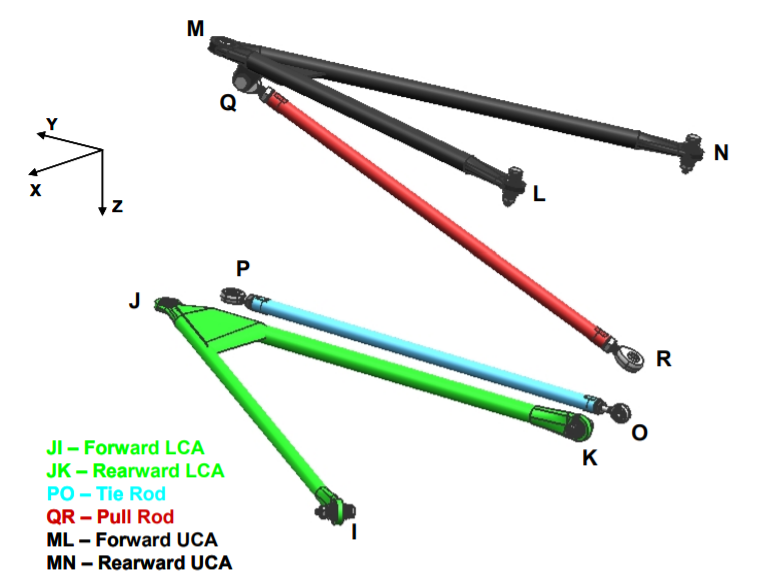

## Part 3: Vectors of Nodes and Their Magnitudes

% Right lower a-arm
JI = [J(1)-I(1) J(2)-I(2) J(3)-I(3)];
ji = sqrt( JI(1)^2 + JI(2)^2 + JI(3)^2);
Zji = JI/ji;


% Left lower a-arm
JK = [J(1)-K(1) J(2)-K(2) J(3)-K(3)];
jk = sqrt( JK(1)^2 + JK(2)^2 + JK(3)^2);
Zjk = JK/jk;


% Toe link
PO = [P(1)-O(1) P(2)-O(2) P(3)-O(3)];
po = sqrt( PO(1)^2 + PO(2)^2 + PO(3)^2);
Zpo = PO/po;


% Pull rod
QR = [Q(1)-R(1) Q(2)-R(2) Q(3)-R(3)];
qr = sqrt( QR(1)^2 + QR(2)^2 + QR(3)^2);
Zqr = QR/qr;

% Right uppper a-arm
ML = [M(1)-L(1) M(2)-L(2) M(3)-L(3)];
ml = sqrt( ML(1)^2 + ML(2)^2 + ML(3)^2);
Zml = ML/ml;

% Left upper a-arm
MN = [M(1)-N(1) M(2)-N(2) M(3)-N(3)];
mn = sqrt( MN(1)^2 + MN(2)^2 + MN(3)^2);
Zmn = MN/mn;

% r-Vector from Wheel Center to Points
rJ = J-UprightCenter;
rK = K-UprightCenter;
rM = M-UprightCenter;
rN = N-UprightCenter;
rP = P-UprightCenter;
rO = O-UprightCenter;
rQ = Q-UprightCenter;
rR = R-UprightCenter;


## Part 5: Solving for each case


% Matrix of the sum of forces in each coordinate direction
A = [Zji(1) Zjk(1) Zml(1) Zmn(1) Zpo(1) Zqr(1);...
     Zji(2) Zjk(2) Zml(2) Zmn(2) Zpo(2) Zqr(2);...
     Zji(3) Zjk(3) Zml(3) Zmn(3) Zpo(3) Zqr(3);...
    (Zji(3)*rJ(2)-Zji(2)*rJ(3)) (Zjk(3)*rJ(1)-Zjk(2)*rJ(3)) (Zml(3)*rM(2)-Zml(2)*rM(3)) (Zmn(3)*rM(2)-Zmn(2)*rM(3)) (Zpo(3)*rO(2)-Zpo(2)*rO(3)) (Zqr(3)*rQ(2)-Zqr(2)*rQ(3));...
    (Zji(3)*rJ(1)-Zji(1)*rJ(3)) (Zjk(3)*rJ(1)-Zjk(1)*rJ(3)) (Zml(3)*rM(1)-Zml(1)*rM(3)) (Zmn(3)*rM(1)-Zmn(1)*rM(3)) (Zpo(3)*rO(1)-Zpo(1)*rO(3)) (Zqr(3)*rQ(1)-Zqr(1)*rQ(3));...
    (Zji(2)*rJ(1)-Zji(1)*rJ(2)) (Zjk(2)*rJ(1)-Zjk(1)*rJ(2)) (Zml(2)*rM(1)-Zml(1)*rM(2)) (Zmn(2)*rM(1)-Zmn(1)*rM(2)) (Zpo(2)*rO(1)-Zpo(1)*rO(2)) (Zqr(2)*rQ(1)-Zqr(1)*rQ(2))];

% % Forces that were acting on the contact patch moved to the center of the
% % upright: their magnitude is the same as at the contact patch
% Fx = 0;
% Fy = -1802;
% Fz = -1135;
% 
% % Moments created on upright center from forces on contact patch (from
% % moment about upright center point)
% Mx = -12.7;
% My = 0;
% Mz = 457.8;

% Vector of forces
b = [Fx; Fy; Fz; Mx; My; Mz];

% solution vector: a vector of forces in each member
X = A\b;

% Renaming solution appropriately:
Fji = X(1);  % Force in front lower a-arm
Fjk = X(2);  % Force in rear lower a-arm
Fml = X(3);  % Force in front upper a-arm
Fmn = X(4);  % Force in rear upper a-arm
Fpo = X(5);  % Force in toe link
Fqr = X(6);  % Force in pull-rod

fprintf("The force in the front lower a-arm is %f Newtons\n", Fji)

The force in the front lower a-arm is -1609.898689 Newtons



fprintf("The force in the rear lower a-arm is %f Newtons\n", Fjk)

The force in the rear lower a-arm is 8228.882997 Newtons



fprintf("The force in the front upper a-arm is %f Newtons\n", Fml)

The force in the front upper a-arm is -75.930394 Newtons



fprintf("The force in the rear upper a-arm is %f Newtons\n", Fmn)

The force in the rear upper a-arm is -22294.704745 Newtons



fprintf("The force in the toe link is %f Newtons\n", Fpo)

The force in the toe link is -1600.012021 Newtons



fprintf("The force in the pull rod is %f Newtons\n", Fqr)

The force in the pull rod is 21462.133541 Newtons



disp ("===========================================")


fprintf("The max case x Force is %f N\n", Mx)

The max case x Force is 891273.470688 N



fprintf("The max case y Force is %f N\n", My)

The max case y Force is 891273.470688 N



fprintf("The max case z Force is %f N\n", Mz)

The max case z Force is 142463.397283 N



fprintf("The max case x moment is %f N-m\n", Mx)

The max case x moment is 891273.470688 N-m



fprintf("The max case y moment is %f N-m\n", My)

The max case y moment is 891273.470688 N-m



fprintf("The max case z moment is %f N-m\n", Mz)

The max case z moment is 142463.397283 N-m


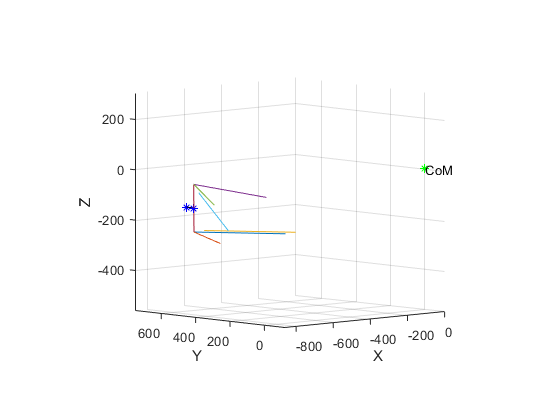




figure(1)

plot3([I(1) J(1)],[I(2) J(2)], [I(3) J(3)]);    % IJ
hold on
plot3([K(1) J(1)],[K(2) J(2)], [K(3) J(3)]);    % KJ
plot3([O(1) P(1)],[O(2) P(2)], [O(3) P(3)]);    % OP
plot3([L(1) M(1)],[L(2) M(2)], [L(3) M(3)]);    % LM
plot3([N(1) M(1)],[N(2) M(2)], [N(3) M(3)]);    % NM
plot3([Q(1) R(1)],[Q(2) R(2)], [Q(3) R(3)]);    % QR
plot3([J(1) M(1)],[J(2) M(2)], [J(3) M(3)]);    % JM
plot3(UprightCenter(1), UprightCenter(2), UprightCenter(3), 'b*');  %text(UprightCenter(1), UprightCenter(2), UprightCenter(3), "UC");
plot3(wheelCenter(1), wheelCenter(2), wheelCenter(3), 'b*');

plot3([UprightCenter(1) wheelCenter(1)], [UprightCenter(2) wheelCenter(2)], [UprightCenter(3), wheelCenter(3)], 'k');
plot3(0,0,0,'g*');  text(0,0,0,"CoM")

xlabel X; ylabel Y; zlabel Z
axis vis3d
grid on
daspect([1 1 1])